%defining input variables
R = 6;
C = 1*10.^-6;
L1 = 4.7*10.^-6;
L2 = 4.7*10.^-6;
L = (L1*L2)/(L1+L2);

%defining characteristic polynomial coefficents as a function of RLC
ap = C*L;
bp = L/R;
cp = C;

%defining exponent values as a function of characteristic polynomial
%coefficents
gamma = (-bp+sqrt(bp^2-4*ap*cp))/(2*ap);
%separating into imag and real for eulers
alpha = real(gamma);
beta = imag(gamma);

%defining bounds of graphs
xmin = 1000;
xmax = 10000;
ymin = 11;
ymax = 13;

%read randomized data from .txt file
datafile = fopen("415 Data.txt", 'r');
Vin=fscanf(datafile,'%f');
fclose(datafile);

%initalize voltage before step response
 v = zeros(1,length(Vin));
 C1 = calcC1(Vin(1), alpha, 12);
 C2 = calcC2(alpha, beta, 1, 1);
 vindex = 1; % x = time at which voltage has been at current response
 v(vindex) = exp(alpha)*(C1*cos(beta)+C2*sin(beta)) + Vin(1)

v =    NaN     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


 C1 = calcC1(Vin(1), alpha, v(1));
 C2 = calcC2(alpha, beta, v(1), 12);
 vindex = 2;
 v(vindex) = exp(alpha)*(C1*cos(beta)+C2*sin(beta)) + Vin(2)

v =    NaN   NaN     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


 input = 1;
 x = 0

x = 0

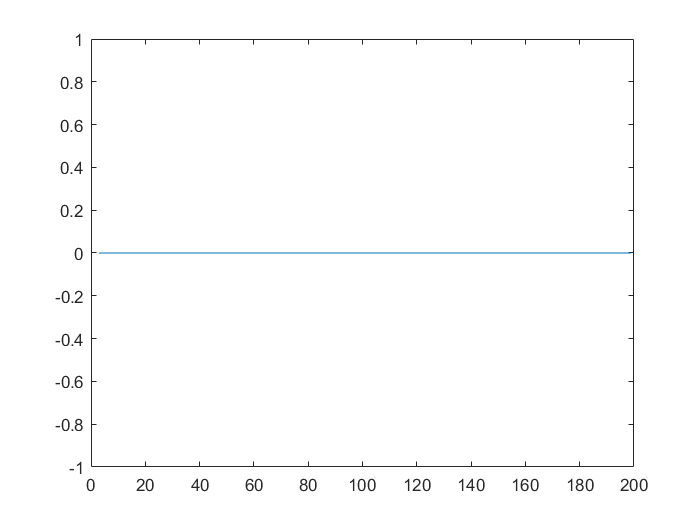


%testing loop
for vindex=200:length(v) %for 10000 input voltage data points
    
    if (mod(vindex, 100) == 0 && vindex ~=0)
    if (Vin(vindex/100) ~= Vin(vindex/100-1)) %if the input voltage has changed initiate new step response
        C1 = calcC1(Vin(vindex/100), alpha, v(vindex-1));
        C2 = calcC2(alpha, beta, v(vindex-1), v(vindex-2));
        input = vindex/100;
        x = 0; 
    end
    end
   
    v(vindex) = exp(alpha*x)*(C1*cos(beta*x)+C2*sin(beta*x)) + Vin(input);
    x=x+0.01;
    
end

t = linspace(1, 10000, 10000);
plot(t, v);

% axis([xmin,xmax,ymin,ymax]);

function C1 = calcC1(Vin, alpha, Vprev1) %calculate coefficent C1

    C1 = (Vprev1 - Vin)/alpha;

end

%calculate coefficent C2
function C2 = calcC2(alpha, beta, Vprev1, Vprev2)

    C2 = (Vprev1-Vprev2)/(alpha*beta);

end
